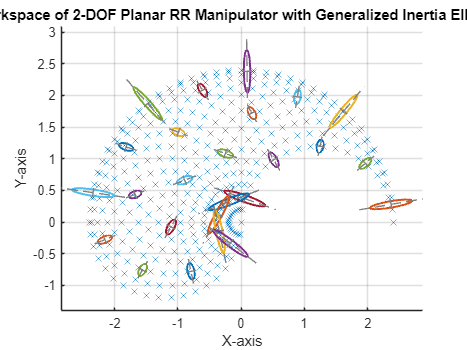

close
clear all
clc
% Parameters
L1 = 1.2;  % Length of the first link (m)
L2 = 1.2;  % Length of the second link (m)
g1 = 0.6; % Center of mass distance from the first joint (m)
g2 = 0.6; % Center of mass distance from the second joint (m)
m1 = 74.4;   % Mass of the first link (kg) = (1550kg/m3) * (0.2*0.2*1.2 m3)
m2 = 74.4;   % Mass of the second link (kg)
I1 = 35.712;    % Moment of inertia of the first link (kgm^2)
I2 = 35.712;    % Moment of inertia of the second link (kgm^2)

% % Parameters
% L1 = 0.4;  % Length of the first link (m)
% L2 = 0.6;  % Length of the second link (m)
% g1 = 0.0; % Center of mass distance from the first joint (m)
% g2 = 0.42; % Center of mass distance from the second joint (m)
% m1 = 50;   % Mass of the first link (kg)
% m2 = 30;   % Mass of the second link (kg)
% I1 = 1.552;    % Moment of inertia of the first link (kgm^2)
% I2 = 9;    % Moment of inertia of the second link (kgm^2)

% Parameters
% L1 = 0.6;  % Length of the first link (m)
% L2 = 0.4;  % Length of the second link (m)
% g1 = 0.0; % Center of mass distance from the first joint (m)
% g2 = 0.28; % Center of mass distance from the second joint (m)
% m1 = 50;   % Mass of the first link (kg)
% m2 = 30;   % Mass of the second link (kg)
% I1 = 3.492;    % Moment of inertia of the first link (kgm^2)
% I2 = 4;    % Moment of inertia of the second link (kgm^2)

% Joint angles
% theta1_range = linspace(-pi/4, pi/4, 20);
% theta2_range = linspace(0, pi/2, 20);

theta1_range = linspace(0, pi, 20);
theta2_range = linspace(0, pi, 20);

% Initialize workspace points
X = [];
Y = [];

% Compute forward kinematics and workspace
for theta1 = theta1_range
    for theta2 = theta2_range
        x = L1 * cos(theta1) + L2 * cos(theta1 + theta2);
        y = L1 * sin(theta1) + L2 * sin(theta1 + theta2);
        X = [X, x];
        Y = [Y, y];
    end
end

% Plot workspace
figure;
scatter(X, Y, 'x');
xlabel('X-axis');
ylabel('Y-axis');
title('Workspace of 2-DOF Planar RR Manipulator with Generalized Inertia Ellipsoid');
grid on;
axis equal;
hold on;

% Function to plot the GIE at a specific configuration

offset = 0.1;
% Plot GIE at several points in the workspace
% theta2_points = [0, pi/4, pi/2, 3*pi/4, pi-offset]/2;
% theta1_points = [0, pi/3, 2*pi/3, pi-offset]/2 - pi/4;

theta1_points = linspace(0, pi, 5)*0.9;
theta2_points = linspace(pi/12, pi, 5)*0.9;

for theta1 = theta1_points
    for theta2 = theta2_points
        plotGIE(theta1, theta2, L1, L2, m1, m2, g1, g2, I1, I2);
    end
end

hold off;


  % H1 = I1 + m1*g2^2*L1^2;
  %   H2 = I2 + m2*g2^2;
  %   H3 = m2*L1*g2*cos(theta1-theta2);
  %   H = [H1, H3; H3, H2];
  % 
  %   R = inv(J);
  %   G = R'*H*R; % Generalized Inertia Tensor

  function plotGIE(theta1, theta2, L1, L2, m1, m2, g1, g2, I1, I2)
    % Jacobian matrix for a 2-DOF planar RR manipulator
    J = [-L1*sin(theta1) - L2*sin(theta1 + theta2), -L2*sin(theta1 + theta2);
          L1*cos(theta1) + L2*cos(theta1 + theta2),  L2*cos(theta1 + theta2)];
      
    % Mass matrix (inertia tensor)
    M = [I1 + I2 + m1*g1^2 + m2*(L1^2 + g2^2), I2 + m2*L1*g2*cos(theta2);
         I2 + m2*L1*g2*cos(theta2), I2 + m2*g2^2];

    % 
    % H1 = I1 + m1*g2^2*L1^2;
    % H2 = I2 + m2*g2^2;
    % H3 = m2*L1*g2*cos(theta1-theta2);
    % H = [H1, H3; H3, H2];
    % M = H;
    % 
    % Generalized inertia tensor in Cartesian coordinates
    G = inv(J * inv(M) * J');
    
    % Eigenvalues and eigenvectors for the ellipsoid axes
    [V, D] = eig(G);
    eig_values = diag(D);

    % Plot the manipulability ellipsoid
    theta = linspace(0, 2*pi, 100);
    ellipse = [sqrt(eig_values(1)) * cos(theta); sqrt(eig_values(2)) * sin(theta)];
    transformed_ellipse = V * ellipse/120;
    
    % Position of the end-effector
    x = L1 * cos(theta1) + L2 * cos(theta1 + theta2);
    y = L1 * sin(theta1) + L2 * sin(theta1 + theta2);
    
    plot(transformed_ellipse(1, :) + x, transformed_ellipse(2, :) + y, 'LineWidth', 1.5);
    
    % Plot the short and long diameters
    short_diameter = V(:, 1) * sqrt(eig_values(1)) * 2/80;
    long_diameter = V(:, 2) * sqrt(eig_values(2)) * 2/80;
    
    plot([x - short_diameter(1)/2, x + short_diameter(1)/2], [y - short_diameter(2)/2, y + short_diameter(2)/2], '--', 'Color', [0.5, 0.5, 0.5]);
    plot([x - long_diameter(1)/2, x + long_diameter(1)/2], [y - long_diameter(2)/2, y + long_diameter(2)/2], '--', 'Color', [0.5, 0.5, 0.5]);
end